# Basic digital twin for a motor position system

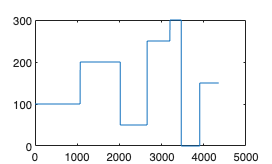

T=readtable('Book2.xlsx');


inputData=T.Var2(387182:391536);
outputData=T.Var3(387182:391536);
ts=1e-3*(T.Var1(2)-T.Var1(1));
sysDataIdent=iddata(outputData,inputData,ts);


figure()
plot(inputData)

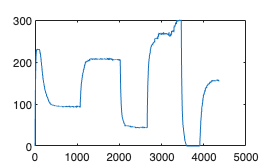

figure()
plot(outputData)

## Performing system closed loop system ID to build a basic digital twin of the system

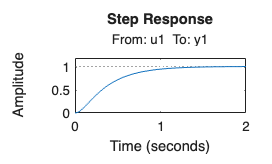

%define PID controller basic transfer function
s = tf('s'); % Define the Laplace variable
Kp = 1; % Proportional gain
Ki = 1; % Integral gain
Kd = 1; % Derivative gain
pidController = Kp + Ki/s + Kd*s; % PID controller transfer function

%estimate a second-order system
sysSecond = procest(sysDataIdent,"P2U");
kp = sysSecond.Kp;
sysSecond.Report;

figure()
step(sysSecond)

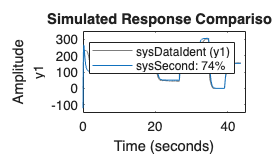

figure()
compare(sysDataIdent,sysSecond)

sysSecond.Report;


%% transforming continuous time TF function into difference equation

[num,den]=tfdata(sysSecond)

num = 1×1 cell array
    {[0 0 1.0160]}


den = 1×1 cell array
    {[0.0288 0.4054 1]}


num=cell2mat(num);
den=cell2mat(den);

DT_TF_Cont=tf(num,den)


DT_TF_Cont =
 
            1.016
  --------------------------
  0.02884 s^2 + 0.4054 s + 1
 
Continuous-time transfer function.


DT_TF_Discrete = c2d(DT_TF_Cont, ts, 'tustin') % Convert continuous TF to discrete


DT_TF_Discrete =
 
  0.0008223 z^2 + 0.001645 z + 0.0008223
  --------------------------------------
          z^2 - 1.866 z + 0.8688
 
Sample time: 0.01 seconds
Discrete-time transfer function.


DT_TF_Discrete.Variable = 'z^-1'; % Define the variable for discrete time

DT_TF_Discrete


DT_TF_Discrete =
 
  0.0008223 + 0.001645 z^-1 + 0.0008223 z^-2
  ------------------------------------------
         1 - 1.866 z^-1 + 0.8688 z^-2
 
Sample time: 0.01 seconds
Discrete-time transfer function.


## performing a quick behavioral matching

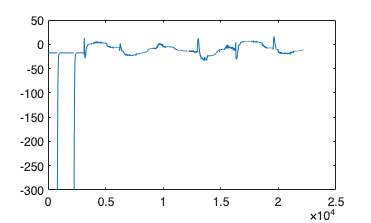

T_DT=readtable('data.txt');

DTOutput=   T_DT.Var5;
systemOutput= T_DT.Var3;


%error calculation

DTError=DTOutput-systemOutput;
figure()
plot(DTError)


%use the mean error to adjust the DT accuracy
DTErrorMean=mean(DTError(0.5e4:end))

DTErrorMean = -10.6556

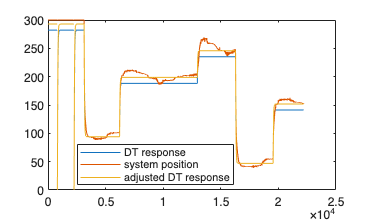




for i=1:length(DTOutput)
    if DTOutput(i)<120
        adjustedDT(i)=DTOutput(i);
    else

        adjustedDT(i)=DTOutput(i)-   DTErrorMean;
    end

end



figure()
plot(DTOutput)
hold on
plot(systemOutput)

plot(adjustedDT)

legend('DT response','system position','adjusted DT response')